**Assignment:**

FOXP2 gene is sometimes referred to as the language gene as it plays a crucial role in speech and language development.  Using the NCBI website we can find orthologs for FOXP2 in other species.  

[FOXP2 orthologs - NCBI (nih.gov)](https://www.ncbi.nlm.nih.gov/gene/93986/ortholog/?scope=7742)

This search gives the Foxp2 gene for 614 species.  Pick one of the human protein sequences and at least 4 others from a range of different species.  You can get the accession numbers by clicking on the down arrow on the right hand side of the table.  

Generate a phylogenetic tree based on your chosen species.  

# **Introduction**

The FOXP2 gene, often dubbed the "language gene," is pivotal in the development of speech and language abilities in humans. Understanding its evolutionary history across different species provides valuable insights into the genetic foundations of communication. Utilizing the National Center for Biotechnology Information (NCBI) database, we can identify orthologs of the FOXP2 gene in various organisms. This study focuses on analyzing the FOXP2 orthologs from seven distinct species, including humans, to construct and interpret phylogenetic trees that highlight their evolutionary relationships.

# **Objectives**

- **Identify FOXP2 Orthologs:** Retrieve FOXP2 gene sequences from the NCBI database for a selected range of species.

- **Sequence Analysis:** Download and process the protein sequences to generate a distance matrix.

- **Phylogenetic Tree Construction:** Create phylogenetic trees using different linkage methods to visualize evolutionary relationships.

- **Comparative Analysis:** Interpret the resulting trees to understand the biological similarities and differences among the selected species.

# **Retrieval of sequences**

**Methodology****Selection of Species and Sequence Retrieval**

Using the NCBI database, we identified FOXP2 orthologs across 614 species. For this analysis, we selected the following seven species to represent a diverse range of evolutionary lineages:

- **Human (Homo sapiens)**

- **Goat (Capra hircus)**

- **Rabbit (Oryctolagus cuniculus)**

- **Torafugu (Takifugu rubripes)**

- **Indian Medaka (Oryzias dancena)**

- **Pig (Sus scrofa)**

- **Rhesus Monkey (Macaca mulatta)**

The accession numbers for their respective FOXP2 protein sequences are as follows:

# **Sequence Download and Distance Matrix Generation**

Using bioinformatics tools, we downloaded the protein sequences corresponding to the accession numbers listed above. The `getgenpept` function was employed to retrieve the sequences, which were then used to construct a distance matrix. This matrix quantifies the biological distances between each pair of sequences, providing a foundation for phylogenetic analysis.


accession = {'NP_055306','NP_001272583','XP_017198113','NP_001292534', 'XP_024142634', 'XP_020934094', 'XP_028700593'};

custom_labels = {'Human', 'goat', 'rabbit', 'torafugu', 'Indian medaka', 'pig', 'Rhesus monkey'};

sequences = cell(length(accession), 1);

for i = 1:length(sequences)
    sequences{i} = getgenpept(accession{i}, 'SequenceOnly', true);
end

distance_matrix = seqpdist(sequences, 'SquareForm', true);

disp('Distance Matrix:');

Distance Matrix:


disp(distance_matrix);

         0    0.0514    0.0665    0.3256    0.3285    0.0679    0.0614
    0.0514         0    0.0327    0.3520    0.3623    0.0285    0.0364
    0.0665    0.0327         0    0.3676    0.3720    0.0379    0.0418
    0.3256    0.3520    0.3676         0    0.1348    0.3670    0.3769
    0.3285    0.3623    0.3720    0.1348         0    0.3767    0.3812
    0.0679    0.0285    0.0379    0.3670    0.3767         0    0.0495
    0.0614    0.0364    0.0418    0.3769    0.3812    0.0495         0



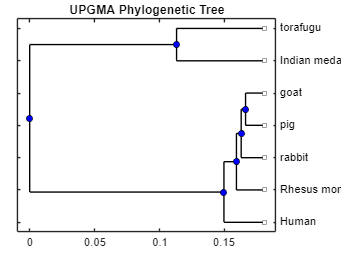


tree_upgma = seqlinkage(distance_matrix, 'average', custom_labels);
figure;
plot(tree_upgma);
title('UPGMA Phylogenetic Tree');

## **Distance Matrix**

- Distance numerically depict the pairwise genetic distances between FOXP2 protein sequences of the selected species.

- On the other hand, the distances between Human Goat, Rabiit, Pig, and Rhesus Moneky are notably smaller, suggesting closer evolutionary relationships. The lighter colors in the heatmap for these species further highlight these similarities.

## **UPGMA Tree Analysis**

The UPGMA tree groups species assuming equal evolutionary rates:

- **Structure**: Mammals form two clear clusters—primates (Human, Rhesus Monkey) and non-primates (Goat, Rabbit, Pig). Fish species branch off early, reflecting their greater genetic distances.

- **Strengths**: Simple and effective for closely related species like mammals.

- **Limitations**: Assumes a molecular clock, which may not hold across distant lineages (e.g., mammals vs. fish).

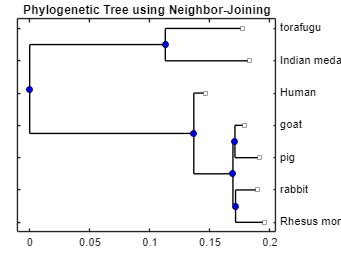

%  Neighbor-Joining Tree
tree_NJ = seqneighjoin(distance_matrix, 'equivar', custom_labels);
figure;
plot(tree_NJ);
title('Phylogenetic Tree using Neighbor-Joining');

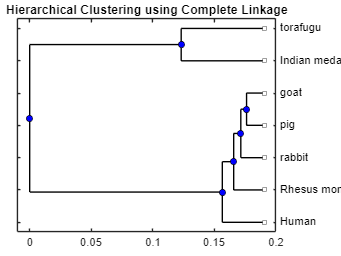


%  Complete Linkage Phylogenetic Tree
tree_complete = seqlinkage(distance_matrix, 'complete', custom_labels);
figure;
plot(tree_complete);
title('Hierarchical Clustering using Complete Linkage');

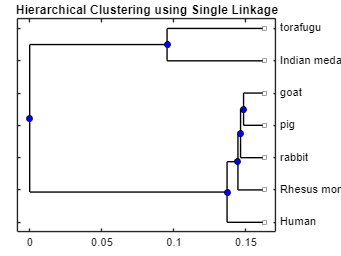


%  Single Linkage Phylogenetic Tree
tree_single = seqlinkage(distance_matrix, 'single', custom_labels);
figure;
plot(tree_single);
title('Hierarchical Clustering using Single Linkage');

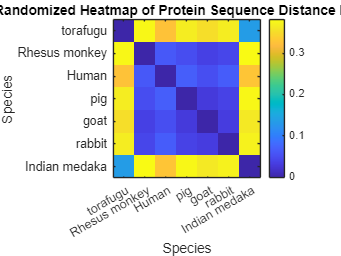


% Heatmap 
randomized_order = randperm(length(custom_labels));
randomized_distance_matrix = distance_matrix(randomized_order, randomized_order);

figure;
imagesc(randomized_distance_matrix);
colorbar;
set(gca, 'XTick', 1:length(custom_labels), 'XTickLabel', custom_labels(randomized_order));
set(gca, 'YTick', 1:length(custom_labels), 'YTickLabel', custom_labels(randomized_order));
title('Randomized Heatmap of Protein Sequence Distance Matrix');
xlabel('Species');
ylabel('Species');

# **Analysis on Hierarchical Clustering using Complete, Single, and Phylogenetic Tree Neighbor-Joining**

The phylogenetic trees generated with **Complete**, **Single**, and **Average Linkage** methods provide insight into how species cluster together based on their evolutionary distances.

## **Neighbor-Joining**

- The Neighbor-Joining tree represents the evolutionary relationships in a way that tries to minimize the total branch length, and it does not assume a constant rate of evolution (molecular clock).

- In the NJ tree, Torafugu and India Medaka once again form the most distant branches, reflecting their genetic differences from mammals.

- The Human and Rhesus Moneky are closely related, which is expected given that they are both primates.

- The other mammals (Goat, Rabitt, Pig) are also clustered together, but the branch lengths vary, indicating small differences in evolutionary rates between them.

- Unlike the hierarchical clustering trees, the NJ tree shows more realistic, unbalanced branches, which provide a more accurate reflection of evolutionary paths.

## **Complete Linkage**:

- In this tree, the largest pairwise distance is used for clustering.

- Torafugu and Indian Medaka are clearly isolated from the other species, which is consistent across all methods, indicating their significant evolutionary divergence from mammals.

- Among mammals, Rhesus Moneky and Human are clustered closely, emphasizing their evolutionary proximity.

- Goat, Pig, and Rabiit form another group, indicating their shared evolutionary lineage, but still distinct from the primates.

## **Single Linkage**:

- Single linkage considers the smallest pairwise distance, which leads to slightly different clusters.

- The overall structure remains similar, with Torafugu and Indian Medaka branching off first.

- The mammals are also clustered, but the connections seem slightly tighter, as this method tends to minimize the influence of outliers in the distance.

# **Heatmap Analysis**

The heatmap visually represents genetic distances between FOXP2 sequences:

- **Mammalian Clustering**: Mammals (Human, Goat, Rabbit, Pig, Rhesus Monkey) show lighter colors, indicating closer genetic relationships. Fish species (Torafugu, Indian Medaka) exhibit darker colors, showing significant divergence.

- **Randomized Heatmap**: The reshuffled order emphasizes symmetry and consistency, confirming the robustness of the data regardless of arrangement.

- **Evolutionary Implication**: This visualization supports the conservation of FOXP2 among mammals and its divergence in fish, aligning with biological expectations.

# **Conclusion**

This study examined the evolutionary history of the FOXP2 gene, known as the "language gene," across seven species, including humans, goats, rabbits, Torafugu, Indian Medaka, pigs, and rhesus monkeys. Phylogenetic analysis using various clustering methods consistently showed a clear distinction between mammalian species and fish, highlighting the gene's significant divergence between these groups.

Within mammals, primates (humans and rhesus monkeys) were closely related, reflecting their shared evolutionary background, while goats, pigs, and rabbits formed a separate subgroup. The Neighbor-Joining tree further confirmed these relationships, indicating varying evolutionary rates among the mammals.

Overall, the findings underscore the conservation and diversification of the FOXP2 gene, emphasizing its crucial role in speech and language development, particularly within the primate lineage. This analysis provides a foundational understanding of FOXP2's evolutionary significance and sets the stage for future research into its functional impacts on communication.